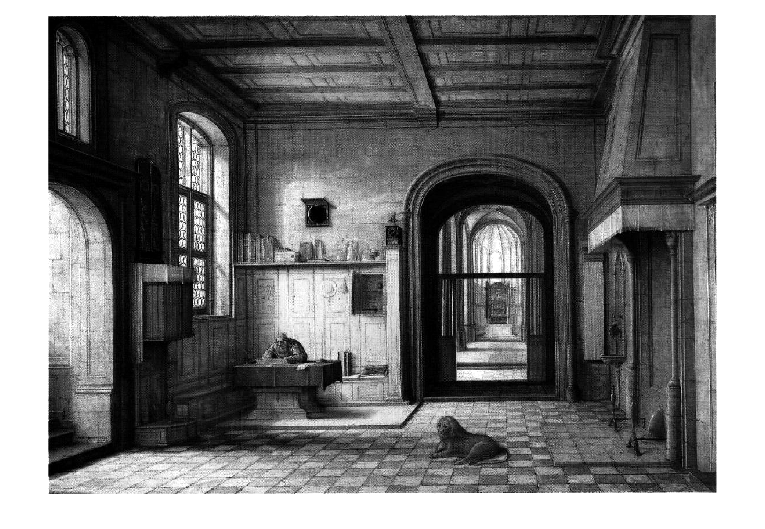

% TIP basic algorithmus
% Vanishing points analysis
% Version: 1.1
% Last change: 25.06.2024
% Author: Cheng Chen

clc;
clearvars;

%% Image prepration
% import image, converting it to grayscale and enhacing the contrast 
% to better delineate edges and lines

%------------------------------- TODO --------------------------------------
% choose different image input to adjust parameters
%img = im2double(imread('test.jpg'));
% easy
%img = im2double(imread('simple-room.png'));
img = im2double(imread('oil-painting.png'));

% middel
%img = im2double(imread('shopping-mall.png'));
%img = im2double(imread('uhren-turm.jpg'));

% difficult
%img = im2double(imread('metro-station.png'));
%img = im2double(imread('sagrada_familia.png'));
%------------------------------- TODO end -----------------------------------

gray = rgb2gray(img);
gray = imadjust(gray);
imshow(gray);

%{
% 1.Separate Foreground and Background

% Use ginput function to allow user selection of corners
[x, y] = ginput;
% Show the selected points
hold on;
plot(x, y, 'r*'); % Display the selected corners
% Create the polygon mask
mask = poly2mask(x, y, size(img, 1), size(img, 2));
% Display the mask
figure;
imshow(mask);
% Apply mask to extract the foreground
foreground = img;
foreground(~mask) = 0; % Set pixels outside the mask to 0 or another background value
% Display the extracted foreground
figure;
imshow(foreground);
%{
[B, L] = bwboundaries(edges, 'noholes');

figure; imshow(gray); hold on;
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 1);
end
hold off;
%}

%{
% Extract the foreground
foreground = gray .* foreground_mask;
% Extract the background
background = gray .* ~foreground_mask;
% Display the extracted foreground and background
figure;
imshow(foreground);
imshow(background);
%}
%}

% 2.Background reconstruction
% 2.1 Perspective analysis

%% Edge detection
% using Canny detector to identify edges, which will used for recgnize
% perspective lines

%------------------------------- TODO --------------------------------------
% adjust threshold and method('soble','prewitt','roberts'...) for
% different image input
[edges, threshold] = edge(gray, 'canny');
disp(threshold);

    0.0438    0.1094



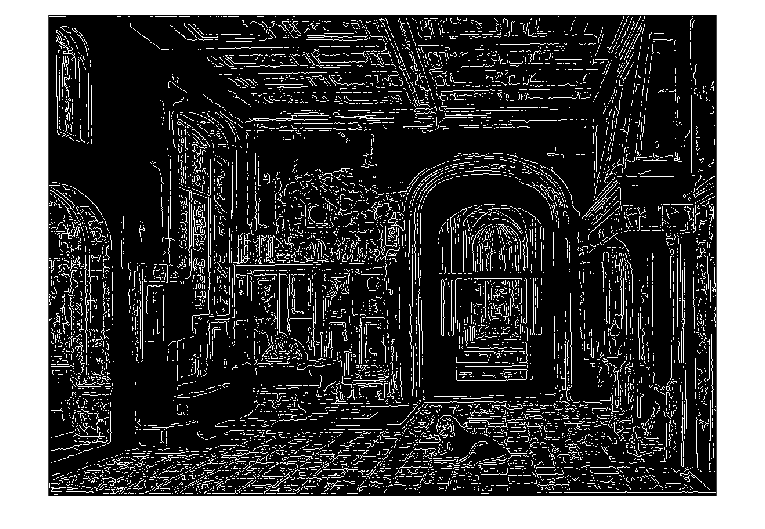

%threshold = 0.07;
%edges = edge(gray, 'sobel', threshold);
%------------------------------- TODO end -----------------------------------
imshow(edges);

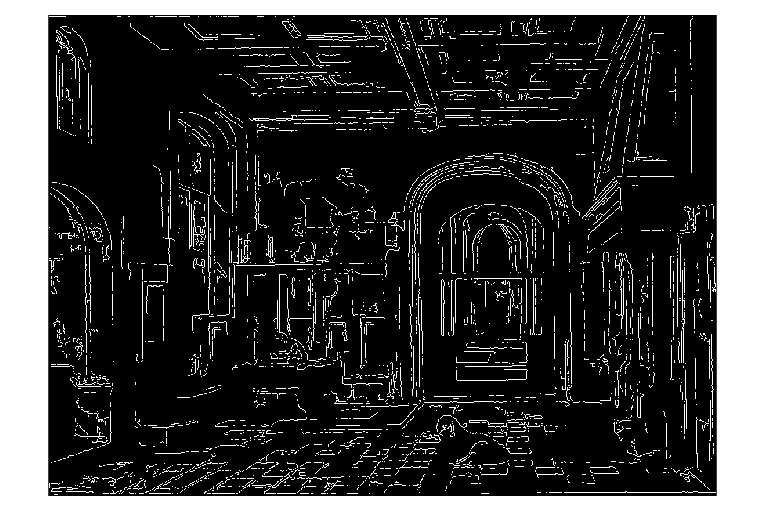


%% Edge filtering
% Filtering out small objects is crucial to reduce noise
% in the Hough Transform process
%------------------------------- TODO --------------------------------------
% adjust minimum area threshold
minArea = 100;
%------------------------------- TODO end -----------------------------------
filtered_edges = bwareaopen(edges, minArea);
imshow(filtered_edges);

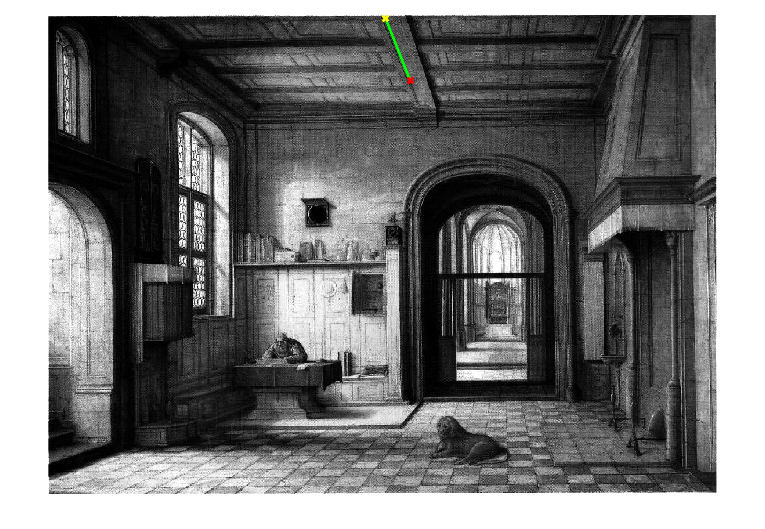


%% Lines detection using Hough Transform
% apply the Hough Transform to detect lines from the edge, which 
% will be used for subsequent vanishing point analysis.
[H, theta, rho] = hough(filtered_edges);
%------------------------------- TODO --------------------------------------
% adjust value of 'numpeaks', 'FillGap' and 'Minlength'
peaks = houghpeaks(H, 100, 'Threshold', ceil(0.3*max(H(:))));
lines = houghlines(edges, theta, rho, peaks, 'FillGap', 5, 'MinLength',100);
%------------------------------- TODO end -----------------------------------

prespectiv_lines = lines;
% threshold angle for filtering (adjust as necessary)
threshold_angle = 10;

% Filter out nearly horizontal and vertical lines
prespectiv_lines = prespectiv_lines(arrayfun(@(line) ...
    abs(line.theta) > threshold_angle && ...
    abs(line.theta) < (90 - threshold_angle), prespectiv_lines));

% Display detected lines
figure, imshow(gray), hold on;
max_len = 0;
for k = 1:length(prespectiv_lines)
    xy = [prespectiv_lines(k).point1; prespectiv_lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
    % Plot beginnings and ends of lines
    plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
end
hold off;


%% Vanishing point analysis
% calculate intersections from the lines obtained from the Hough Transform,
% these intersections are potential vanishing points

% Simple clustering of vanishing points
points = [];
for i = 1:length(prespectiv_lines)
    for j = i+1:length(prespectiv_lines)
        [x, y] = intersection(prespectiv_lines(i), prespectiv_lines(j));
        if ~isnan(x) && ~isnan(y)
            points = [points; x, y];
        end
    end
end

% Clustering
if ~isempty(points)
    vanish_point = mean(points, 1);
    figure, imshow(gray), hold on;
    plot(vanish_point(1), vanish_point(2), 'r+', 'MarkerSize', 10, 'LineWidth', 2);
end

%{
%% Horizon line analysis
if ~isempty(points)
    % Use DBSCAN clustering method to find clusters
    %------------------------------- TODO --------------------------------------
    % Parameters need adjustment
    [labels, numClusters] = dbscan(points, 2, 5);
    %------------------------------- TODO end -----------------------------------
    validClusters = labels ~= -1;  % Filtering out noise
    clusteredPoints = points(validClusters, :);
    
    % Use RANSAC to fit a line to the clustered points
    [lineModel, inlierIdx] = fitLineRANSAC(clusteredPoints, 2.0); % Tolerance may need adjustments
    inlierPoints = clusteredPoints(inlierIdx, :);

    % Plot inliers for visual inspection
    plot(inlierPoints(:,1), inlierPoints(:,2), 'go');
    % Draw the line
    xLimits = xlim();
    yFitted = polyval(lineModel, xLimits);
    plot(xLimits, yFitted, 'r-', 'LineWidth', 2);
end
%}
%}

function [x, y] = intersection(line1, line2)
% calculating the intersection of 2 lines

    % Extracting parameters from the lines
    theta1 = line1.theta * pi / 180; % Convert degrees to radians
    rho1 = line1.rho;
    theta2 = line2.theta * pi / 180;
    rho2 = line2.rho;
    
    % Constructing matrix equation Ax = b
    A = [cos(theta1) sin(theta1); cos(theta2) sin(theta2)];
    b = [rho1; rho2];
    
    % Solve the linear equations using matrix left division
    if rank(A) == 2 % Only solve if the matrix is full rank
        x = A \ b;
        y = x(2);
        x = x(1);
    else
        x = NaN; % No solution
        y = NaN;
    end
end

function [model, inlierIdx] = fitLineRANSAC(points, tolerance)
    % Fit line using RANSAC to better handle outliers
    [model, inlierIdx] = ransac(points, @(x) polyfit(x(:,1), x(:,2), 1), ...
        @(model, points) abs(polyval(model, points(:,1)) - points(:,2)) < tolerance, ...
        size(points,1), 0.5 * size(points, 1));  % Adjust iterations and sample count as needed
end

function edgeDensity = calculateEdgeDensity(edges, windowSize)
    % Calculate the local density of edge pixels within a window
    % Create a window with all ones
    window = ones(windowSize, windowSize);
    
    % Use convolution to count the number of edge pixels in the neighborhood
    edgeCounts = conv2(double(edges), window, 'same');
    
    % Normalize by the area of the window to get density
    edgeDensity = edgeCounts / (windowSize * windowSize);
end